# Karakteristika

Fs = 0.2;
Ts = 1/Fs;
T = 300;
t = 0:Ts:T;
N = length(t);
F = 1 / (N * T);
fmax = 1/(2*T);
v = 0:F:(fmax - F); %frequency vector
u = ones(1,(T*Fs)+1);
simin = [t',u'];

% open_system("seminar_simulink")
simy = [];
for i = 0:0.1:2.5
    u = ones(1,(T*Fs)+1)*i;
    simin = [t',u'];
    set_param('seminar_simulink','StopTime',int2str(T));
    sim("seminar_simulink");
    simy = [ans.simouty.Data,simy];
end

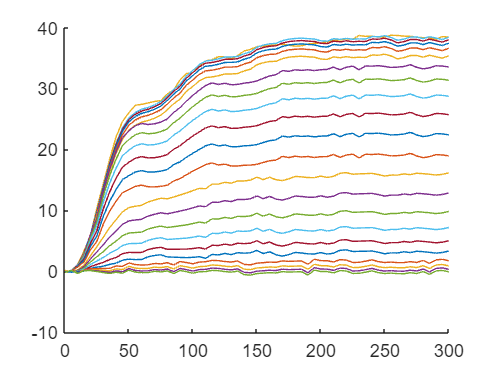

figure;
hold on;
for i = 1:length(simy(1,:))
    plot(t',simy(:,i));
end

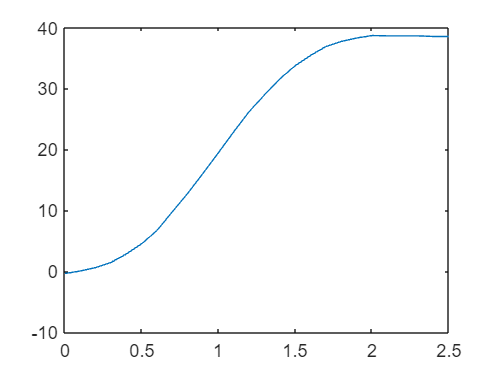

const = [];
for i = 1:length(simy(1,:))
    const = [mean(simy(end-20:end,i)),const];
end
figure
plot(0:0.1:2.5,const)

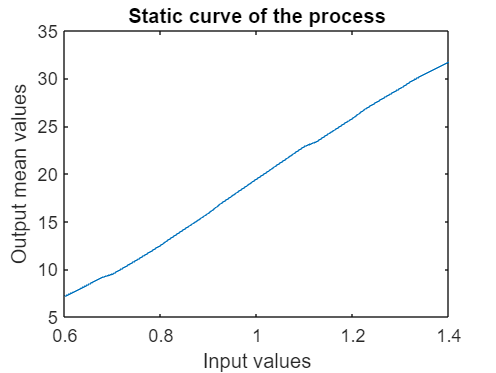

% open_system("seminar_simulink")
simy_short = [];
for i = 0.6:0.025:1.4
    u = ones(1,(T*Fs)+1)*i;
    simin = [t',u'];
    set_param('seminar_simulink','StopTime',int2str(T));
    sim("seminar_simulink");
    simy_short = [ans.simouty.Data,simy_short];
end
const_short = [];
for i = 1:length(simy_short(1,:))
    const_short = [mean(simy_short(end-20:end,i)),const_short];
end
figure
plot(0.6:0.025:1.4,const_short)
xlabel("Input values")
ylabel("Output mean values")
title("Static curve of the process")

## Frekvenčni Odziv

Fs = 0.0625;
Ts = 1/Fs;
T = 19200;
t = 0:Ts:T;
N = length(t);
F = 1 / (N * T);
fmax = 1/(2*T);
v = 0:F:(fmax - F); %frequency vector
u = ones(1,(T*Fs)+1);
simin = [t',u'];

U_PRBS = 0.6 + prbs(10)*0.8;
U_const = ones(length(t)-length(U_PRBS),1);
simin_PRBS = [U_const;U_PRBS];
simin = [t',simin_PRBS];
% open_system("seminar_simulink");
set_param('seminar_simulink','StopTime',int2str(T));
sim("seminar_simulink");
simy_PRBS = [simin,ans.simouty.Data];

t = simy_PRBS(1:end-178,1);
u = simy_PRBS(179:end,2)-1;
y = simy_PRBS(179:end,3)-19.1;

t = simy_PRBS(:,1);
u = simy_PRBS(:,2)-1;
y = simy_PRBS(:,3)-19.1;

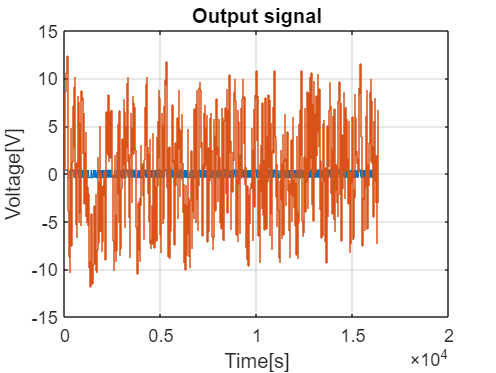

figure
plot(t,u)
hold on
stairs(t,y)
xlabel('Time[s]');
ylabel('Voltage[V]');
title('Output signal');
grid on;

N = length(t);
T = t(2,1) - t(1,1);
F = 1 / (N * T);
fmax = 1/(2*T);
v = 0:F:(fmax - F+F); %frequency vector

## FFT

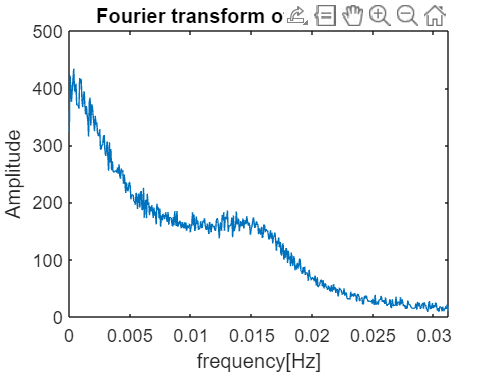

FT_input = fft(u);
FT_output = fft(y);

figure;
plot(v,abs(FT_output(1:(end+1)/2)))
title("Fourier transform of output signal")
xlabel("frequency[Hz]")
ylabel("Amplitude")

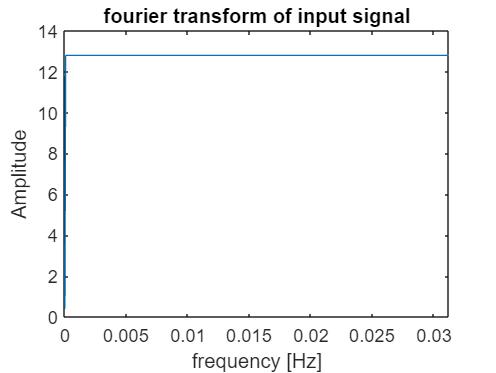


plot(v,abs(FT_input(1:(end+1)/2)))
title("fourier transform of input signal")
xlabel("frequency [Hz]")
ylabel("Amplitude")

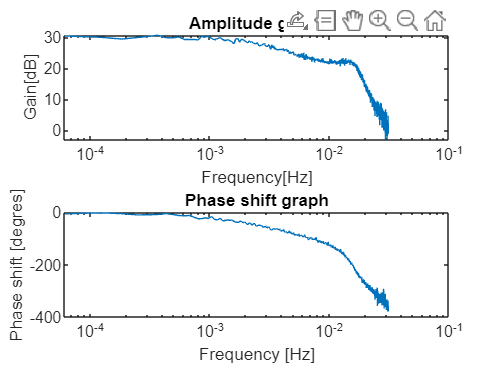

G_jw = FT_output ./ FT_input;
faza = unwrap(angle(G_jw));

subplot(2,1,1), semilogx(v,20*log10(abs(G_jw(1:(end+1)/2))))
title("Amplitude graph")
xlabel("Frequency[Hz]")
ylabel("Gain[dB]")
subplot(2,1,2), semilogx(v,180/pi*(faza(1:(end+1)/2)))
title("Phase shift graph")
xlabel("Frequency [Hz]")
ylabel("Phase shift [degres]")

n = 3;
d = 0;
N = length(y);
num_columns = 1 + n + d;
num_rows = N - n - d; 
k = d + n + 1;
psi = [];

for i = 1:n
    psi = [psi, -y(k-i:N-i)];
end

for i = 1:n
    psi =[psi,u(k-d-i:N-d-i)];
end

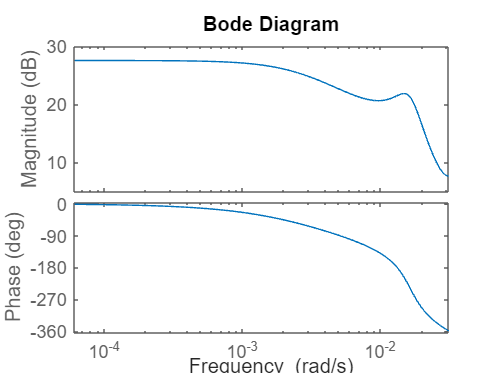


y_short = y((n+d+1):end);
Th = psi \ y_short;
T = T*2*pi;
numerator = Th(n+1:(n*2));
denominator = [1; Th(1:n)];
G = tf(numerator', denominator', T);
G.inputdelay = d;


N = length(t);
T = t(2,1) - t(1,1);
F = 1 / (N * T);
fmax = 1/(2*T);
v = 0:F:(fmax - F + F); %frequency vector

figure
bode(G,v);

[MAG, PH]=bode(G, v);
MAG = MAG(:);
PH = PH(:);
FT_input = fft(u);
FT_output = fft(y);

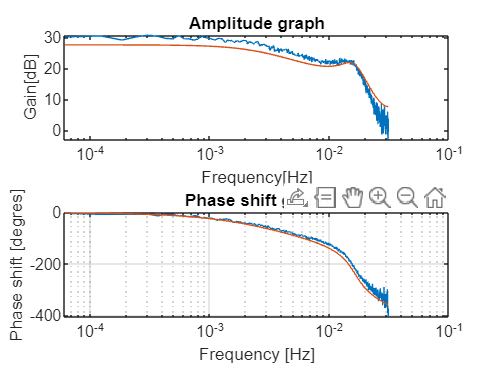

% G_jw = FT_output ./ FT_input;
% faza = unwrap(angle(G_jw));
figure

subplot(2,1,1), semilogx(v,20*log10(abs(G_jw(1:(end+1)/2))))
hold on
subplot(2,1,1), semilogx(v,20*log10(MAG))
title("Amplitude graph")
xlabel("Frequency[Hz]")
ylabel("Gain[dB]")

subplot(2,1,2), semilogx(v,180/pi*(faza(1:(end+1)/2)))
hold on
subplot(2,1,2), semilogx(v,PH)
grid
title("Phase shift graph")
xlabel("Frequency [Hz]")
ylabel("Phase shift [degres]")

## Parametric model 

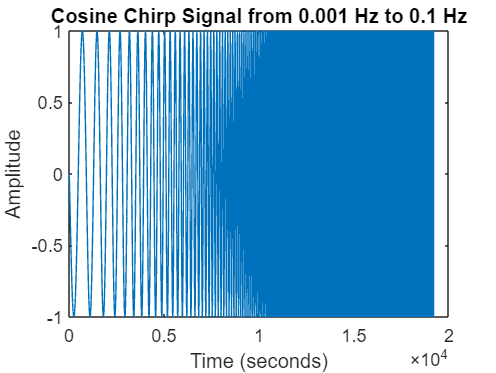

Fs = 10; % Increase the sampling frequency for better resolution
Ts = 1/Fs;
T = 19200;                 % Total time in seconds
t = 0:Ts:T;
% Frequency range
f0 = 0.001;              % Start frequency in Hz
f1 = 0.1;                 % End frequency in Hz

% Generate the cosine chirp signal
% Adding 'phase', pi/2 to generate a cosine instead of a sine wave chirp
signal = chirp(t, f0, T, f1, 'logarithmic', 90); % phase in degrees

% Plot the signal
figure;
plot(t, signal);
title('Cosine Chirp Signal from 0.001 Hz to 0.1 Hz');
xlabel('Time (seconds)');
ylabel('Amplitude');


% Optionally, you can listen to the signal if you want to check its acoustic characteristics
% sound(signal, Fs); % Uncomment this line if you want to listen to the signal

temp = (signal)'+1;
oness = ones(1,6000);
U_true = [oness';temp];
t = 0:Ts:19200 + 600;
simin = [t', U_true];

%v simulinku spremeni čas na 260
% sampling rate pa je 0.01

set_param('seminar_simulink','StopTime',int2str(19200 + 600));
sim("seminar_simulink");
exp_true = [simin,ans.simouty.Data];


t = simy_PRBS(1:end-178,1);
u = simy_PRBS(179:end,2)-1;
y = simy_PRBS(179:end,3)-19.1;

tm = exp_true(1:end-6001,1);
um = exp_true(6002:end,2)-1;
ym = exp_true(6002:end,3)-19.1;

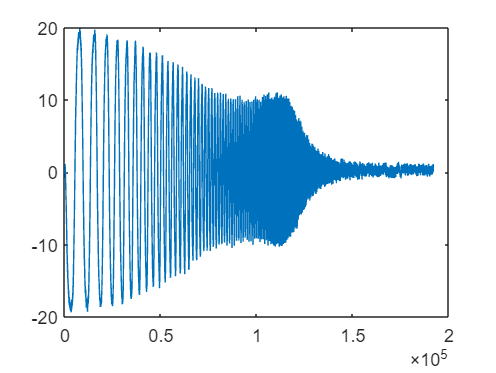

figure
plot(ym)

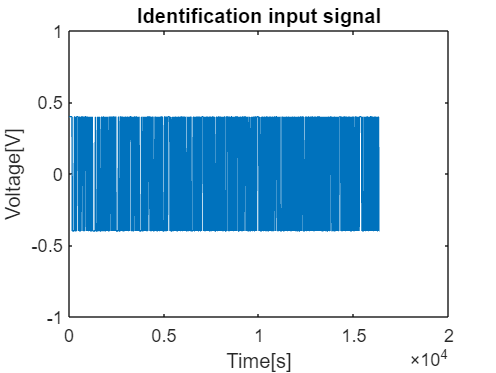

figure
plot(t,u)
% hold on 
% grid on
% stairs(t,y)
ylim([-1 1])
title("Identification input signal")
xlabel("Time[s]")
ylabel("Voltage[V]")

% 
% figure
% plot(tm,-um)
% hold on 
% grid on
% stairs(tm,ym)

N = length(t);
T = t(2,1) - t(1,1);
F = 1 / (N * T);
fmax = 1/(2*T);
v = 0:F:(fmax - F + F); %frequency vector

Nm = length(tm);
Tm = tm(2,1) - tm(1,1);
Fm = 1 / (Nm * Tm);
fmaxm = 1/(2*Tm);
vm = 0:Fm:(fmaxm - Fm); %frequency vector

## FFT

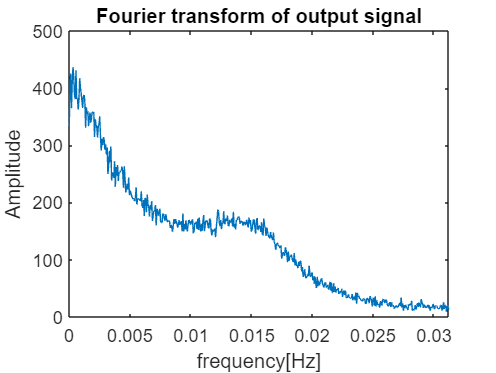

FT_input = fft(u);
FT_output = fft(y);

figure;
plot(v,abs(FT_output(1:(end+1)/2)))
title("Fourier transform of output signal")
xlabel("frequency[Hz]")
ylabel("Amplitude")


plot(v,abs(FT_input(1:(end+1)/2)))
title("fourier transform of input signal")
xlabel("frequency [Hz]")
ylabel("Amplitude")

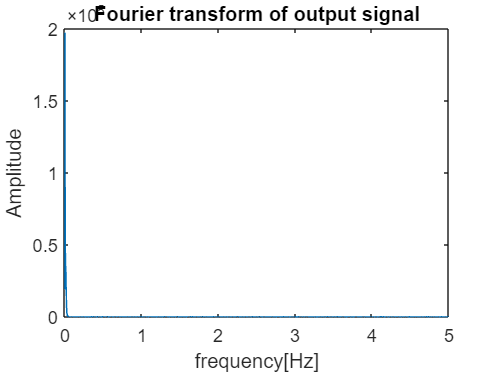


FT_input_m = fft(um);
FT_output_m = fft(ym);

figure;
plot(vm,abs(FT_output_m(1:end/2)))
title("Fourier transform of output signal")
xlabel("frequency[Hz]")
ylabel("Amplitude")

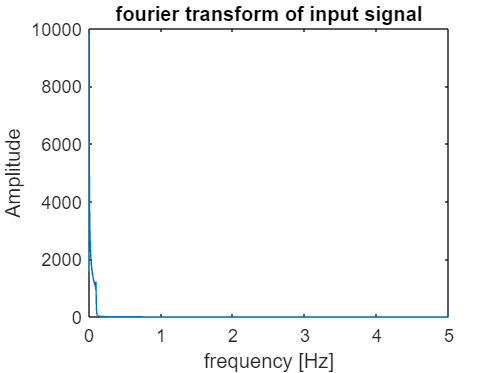


plot(vm,abs(FT_input_m(1:end/2)))
title("fourier transform of input signal")
xlabel("frequency [Hz]")
ylabel("Amplitude")

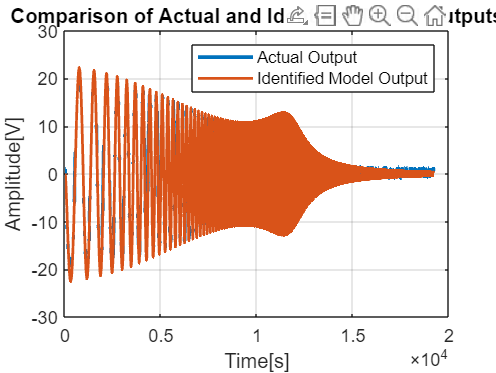

n = 3;
d = 0;
N = length(y);
num_columns = 1 + n + d;
num_rows = N - n - d; 
k = d + n + 1;
psi = [];

for i = 1:n
    psi = [psi, -y(k-i:N-i)];
end

for i = 1:n
    psi =[psi,u(k-d-i:N-d-i)];
end

T = t(2,1) - t(1,1);

y_short = y((n+d+1):end);
Th = psi \ y_short;
Tmp = T;

numerator = Th(n+1:(n*2));
denominator = [1; Th(1:n)];
G = tf(numerator', denominator', Tmp);
G.inputdelay = d;

figure
G_resampled = d2d(G, 0.1);
% bode(G_resampled,v);
[MAG, PH]=bode(G_resampled, v);
MAG = MAG(:);
PH = PH(:);

% G_resampled.inputdelay = 2
ymm = lsim(G_resampled, um, tm);
figure;
plot(tm, ym, 'LineWidth', 2);
hold on;
plot(tm, ymm, 'LineWidth', 1.5);
xlabel('Time[s]');
ylabel('Amplitude[V]');
legend('Actual Output', 'Identified Model Output');
title('Comparison of Actual and Identified Model Outputs');
grid on;


error = ymm - ym;
std_dev = std(error);
disp(['Standard Deviation of the Error: ', num2str(std_dev)]);

Standard Deviation of the Error: 1.9033


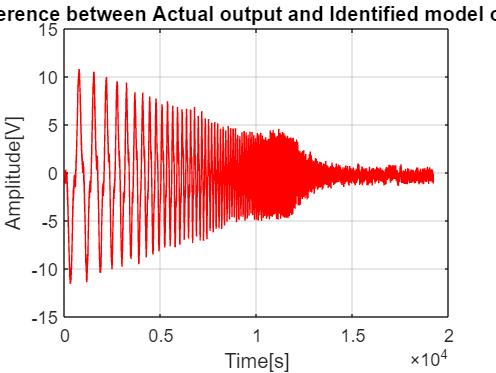

figure
plot(tm, error,"r");
xlabel('Time[s]');
ylabel('Amplitude[V]');
title('Difference between Actual output and Identified model output');
grid on;

% Calculate residuals
y_pred = psi * Th;  % Predicted outputs using the model
residuals = y_short - y_pred;

% Estimate the variance of the residuals
N = size(psi, 1);   % Number of observations
p = size(Th, 1);    % Number of parameters
sigma2 = (residuals' * residuals) / (N - p);

% Calculate covariance matrix of the parameter estimates
Cov_Theta = sigma2 * pinv(psi' * psi);

% Compute standard deviations of the estimates
std_Theta = sqrt(diag(Cov_Theta));

% Display the standard deviations
disp('Standard deviations of the parameters:');

Standard deviations of the parameters:


disp(std_Theta);

    0.0075
    0.0062
    0.0032
    0.0257
    0.0339
    0.0643



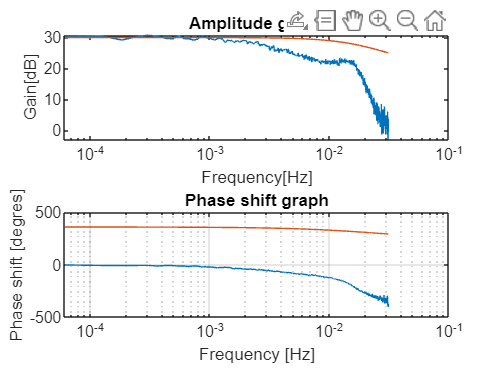


G_jw = FT_output ./ FT_input;
faza = unwrap(angle(G_jw));
figure

subplot(2,1,1), semilogx(v,20*log10(abs(G_jw(1:(end+1)/2))))
hold on
subplot(2,1,1), semilogx(v,20*log10(MAG))
title("Amplitude graph")
xlabel("Frequency[Hz]")
ylabel("Gain[dB]")

subplot(2,1,2), semilogx(v,180/pi*(faza(1:(end+1)/2)))
hold on
subplot(2,1,2), semilogx(v,PH)
grid
title("Phase shift graph")
xlabel("Frequency [Hz]")
ylabel("Phase shift [degres]")